## Examine Data

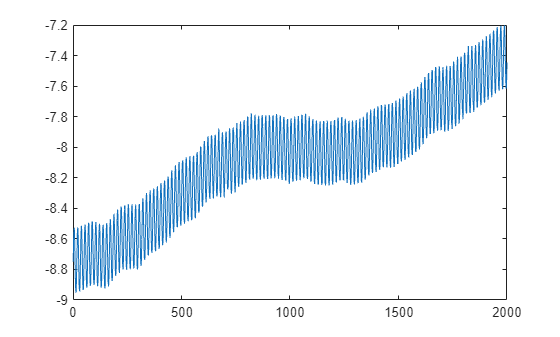

load openloop60hertz.mat
figure
x = 1:numel(openLoopVoltage);
plot(x,openLoopVoltage);

## Develop MATLAB Function

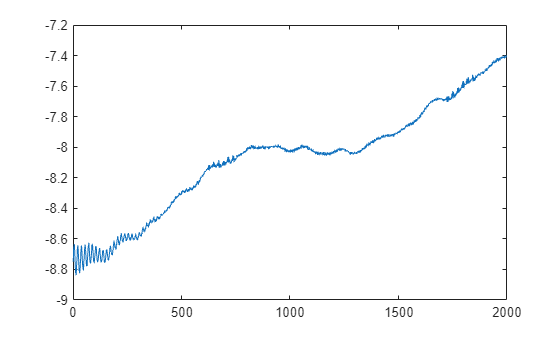

y = cleanSignal(openLoopVoltage,60);
figure
plot(x,y)

## Create and Deploy MCP Archive

hostname = "localhost";
%hostname = "<Your host name here>";
% ctf = prodserver.mcp.build("cleanSignal",definition="cleanSignalMCPTool.json",...
%     wrapper="cleanSignalMCP.m")
ctf = prodserver.mcp.build("cleanSignal");
endpoint = prodserver.mcp.deploy(ctf,hostname,9910)

endpoint = "http://localhost:9910/cleanSignal/mcp"

## Validate Deployment

% Is the server awake?
available = prodserver.mcp.ping(endpoint)

available = logical
   1


% Does the tool exist on the server?
tf = prodserver.mcp.exist(endpoint, "cleanSignal", "Tool")

tf = logical
   1


## Test Deployment

% Can we call the tool on the server?
dataFolder = replace(fileparts(matlab.desktop.editor.getActive().Filename),filesep,"/");
noisy = "file:" + dataFolder + "/" + "openloopVoltage.csv";
clean = "file:" + dataFolder + "/" + "cleanOpenLoop.csv";
frequency = 60;
prodserver.mcp.call(endpoint, "cleanSignal", noisy, frequency, cleanURL=clean)
cleanFile = prodserver.mcp.io.uri.File.FileURI2Path(clean);
cleanVoltage = readmatrix(cleanFile);
figure
plot(x,cleanVoltage)